# Emotion Detection using CNN

## Workflow

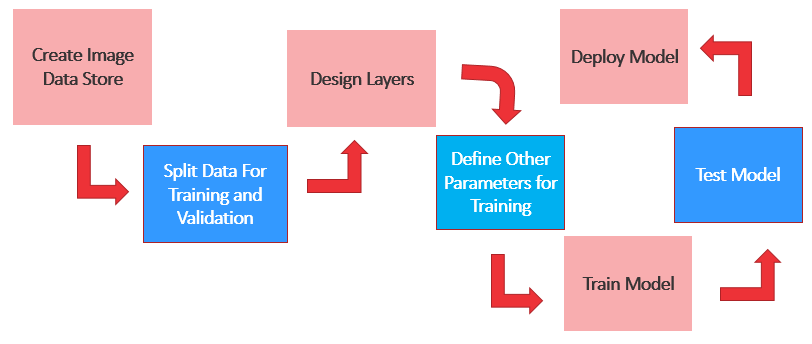

Link for data set [https://www.kaggle.com/shawon10/ckplus](https://www.kaggle.com/shawon10/ckplus)

***Deep learning ***is a type of supervised machine learning in which a  model learns to perform classification tasks directly from images, text,  or sound.

Deep learning is usually implemented using a ***neural network***.

The term “deep” refers to the ***number of layers ***in the network—the  more layers, the deeper the network.

**How CNNs Work**

A convolutional neural network can have hundreds of layers and each layer learn to detect different features of an image. 

Filters are applied to each training image at different resolutions and size, and the output of each convolved image is used as the input to the next layer. 

The filters can start as very simple features, such as brightness and edges, and later on it goes deep to extract complex features.

Like other neural networks, a CNN is composed of an input layer, an output layer, and many hidden layers in between.

## Create Image Datstore

imds = imageDatastore('gesture', ...
        'IncludeSubfolders',true,'LabelSource','foldernames')

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\Desktop\GLA\DL\Emotion_Detection\gesture\anger\S010_004_00000017.png';
                              ' ...\Desktop\GLA\DL\Emotion_Detection\gesture\anger\S010_004_00000018.png';
                              ' ...\Desktop\GLA\DL\Emotion_Detection\gesture\anger\S010_004_00000019.png'
                               ... and 978 more
                              }
                     Folders: {
                              'C:\Users\akhilesh.kumar\Desktop\GLA\DL\Emotion_Detection\gesture'
                              }
                      Labels: [anger; anger; anger ... and 978 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                

##     Split Data for Training and validation

    [imdstrain, imdsvalid]=splitEachLabel(imds,.8,'randomize');
  
     
CountLabel = imds.countEachLabel

CountLabel = 7×2 table
     Label      Count
    ________    _____

    anger        135 
    contempt      54 
    disgust      177 
    fear          75 
    happy        207 
    sadness       84 
    surprise     249 


aa=read(imds);
size(aa)

ans =     48    48


## Define the Network Layers

Define the convolutional neural network architecture. 

layers = [
    imageInputLayer([48 48 1])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(7)
    softmaxLayer
    classificationLayer];  

## Define Option for Training

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',10, ...
    'Shuffle','every-epoch', ...
    'ValidationFrequency',10, ...
    'Verbose',false, ...
    'Plots','training-progress');

## Train Model

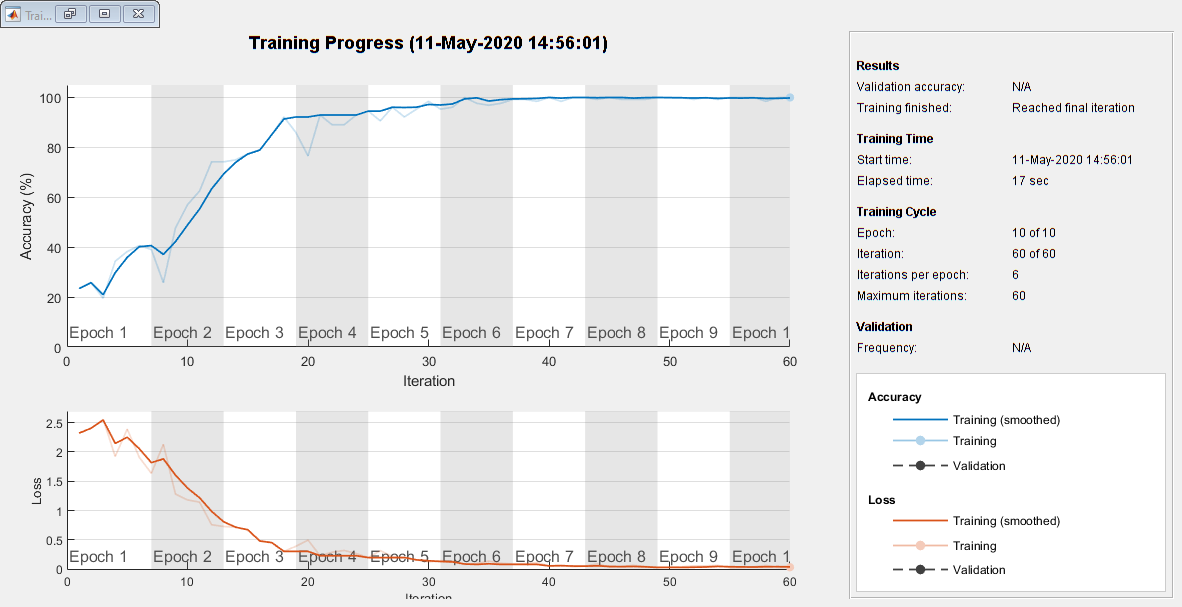


convnet = trainNetwork(imdstrain,layers,options);

## Calaculate Accuracy using Validation Dataset

YPred = classify(convnet,imdsvalid);
YValidation = imdsvalid.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.9745

**Confusion Matrix**

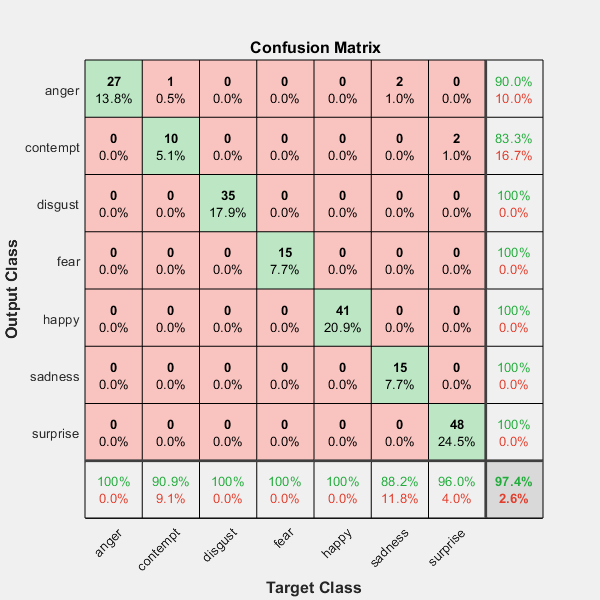

plotconfusion(YValidation,YPred)

**Read an image from datastore and predict the class **

a=read(imdsvalid  );
class=classify(convnet,a)

class = categorical
     anger 


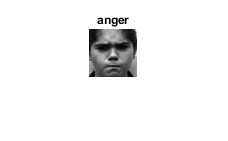

imshow(a)
title(string(class))

## Interface with live Camera

%camera = webcam(1); % Connect to the camera
%camera = ipcam('http://192.168.225.88:8080/video'); % paste the same url as show in the IP Webcam app.
clear camera
figure
camera = webcam(1) % select your webcam

camera =   webcam with properties:

                     Name: 'Integrated Webcam'
     AvailableResolutions: {'640x480'  '160x120'  '320x180'  '320x240'  '424x240'  '640x360'  '848x480'  '960x540'  '1280x720'}
               Resolution: '640x480'
                    Gamma: 100
         WhiteBalanceMode: 'auto'
             ExposureMode: 'auto'
                      Hue: 0
    BacklightCompensation: 3
                 Exposure: -6
             WhiteBalance: 3200
               Brightness: 0
                 Contrast: 0
                Sharpness: 2
               Saturation: 64


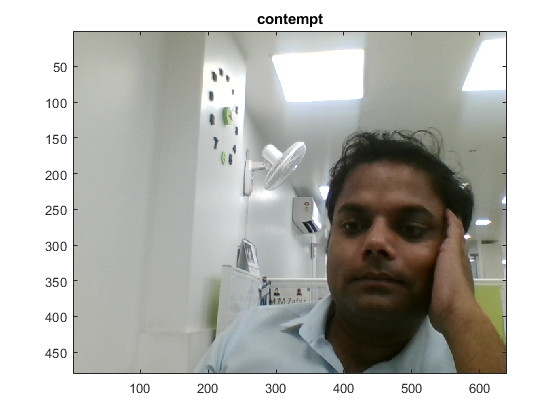


while true   
    im = camera.snapshot;     
    picture=rgb2gray(im);% Take a picture    
    picture = imresize(picture,[48,48]);  % Resize the picture

    label = classify(convnet, picture);        % Classify the picture
       %thingSpeakWrite(467220,0,'WriteKey','H5TEVABDP00IFYKM')

    image(im);     % Show the picture
    title(char(label)); % Show the label
    drawnow;   
end